# Format the Sections of a MATLAB `Table`

This example shows how to format the sections of a DOM table that is created from a MATLAB table.

## Format the Table Header

This example makes the column headings italic. 

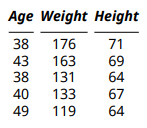

To access the header, use the `Header` property of the `mlreportgen.dom.MATLABTable` object. The example adds an `mlreportgen.dom.Italic` format object to the `Style` property of the `mlreportgen.dom.TableHeader` object that represents the header.

import mlreportgen.dom.*
d = Document('myMATLABTable','pdf');

Age = [38;43;38;40;49];
Height = [71;69;64;67;64];
Weight = [176;163;131;133;119];
mltable = table(Age,Weight,Height);

mltableObj = MATLABTable(mltable);
mltableObj.Header.Style = [mltableObj.Header.Style {Italic(true)}];

append(d,mltableObj);
close(d);
rptview(d);

## Format the Table Body

This example makes the entries of the first row of the table body blue.

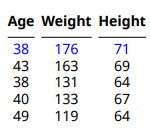

To access the table body, use the `Body` property of the `mlreportgen.dom.MATLABTable` object. To access a row of the body, use the `row` method of the `mlreportgen.dom.TableRow` object that represents the row. The example adds an `mlreportgen.dom.Color` format object to the S`tyle` property of the `TableRow` object that represents the first row.

import mlreportgen.dom.*
d = Document('myMATLABTable','pdf');

Age = [38;43;38;40;49];
Height = [71;69;64;67;64];
Weight = [176;163;131;133;119];
mltable = table(Age,Weight,Height);

mltableObj = MATLABTable(mltable);
tbody = mltableObj.Body;
row1 = row(tbody,1);
row1.Style = [row1.Style {Color('blue')}];

append(d,mltableObj);
close(d);
rptview(d);

*Copyright 2019 The MathWorks, Inc.*